# Check Energy Spectra

## Input h5 Files

fileNameStr = 'C:\Users\nithin\Downloads\20080326.001_bc_15se-energyFlux.h5';
fileNameStr0 = 'G:\My Drive\Research\Projects\Paper 2\Data\Event 1\20080326.001_bc_15sec-fitcal.h5';

## Loading data

data.energyFlux = permute(h5read(fileNameStr,'/energyFluxFromMaxEnt/energyFlux'),[3 2 1]); % in [m^-3]
data.qInput = h5read(fileNameStr,'/energyFluxFromMaxEnt/qInput'); % Need to fix this order
data.qInverted = h5read(fileNameStr,'/energyFluxFromMaxEnt/qInverted');% Need to fix these
data.time = h5read(fileNameStr,'/energyFluxFromMaxEnt/time')';
data.electronDensity = permute(h5read(fileNameStr,'/inputData/Ne'),[3 2 1]);
data.energyBin = h5read(fileNameStr,'/energyFluxFromMaxEnt/energyBin')';
data.alt = h5read(fileNameStr,'/energyFluxFromMaxEnt/alt')';

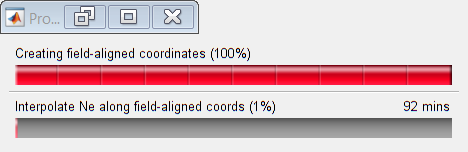

amisr = read_amisr(fileNameStr0);
data.magBeamNo = amisr.magBeamNo;
amisrData= aer_to_field_aligned_coords(amisr,70);

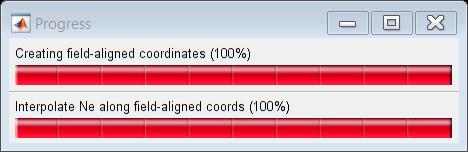

timeMinStr = '26 Mar 2008 11:00:00';
timeMaxStr = '26 Mar 2008 13:00:00';
amisrData = interpolate_to_field_aligned_coords(amisrData,timeMinStr,timeMaxStr);

% clearvars amisr

## Plotting

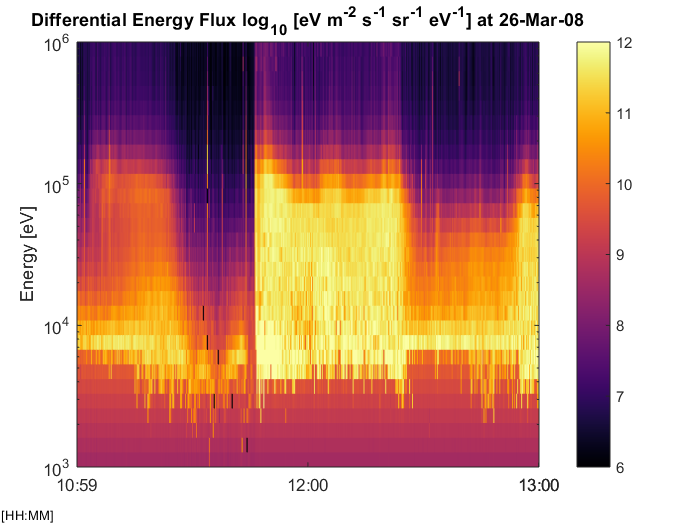

% Time

figure;
% z = squeeze(data.energyFlux(:,data.magBeamNo,:));
z = squeeze(mean(data.energyFlux,2));
z(z<=0)=10^3;
plot_2D_time_series(data.time',data.energyBin',log10(z)',1,3,timeMinStr,timeMaxStr);
colormap('inferno');
caxis([6 12]);
colorbar;

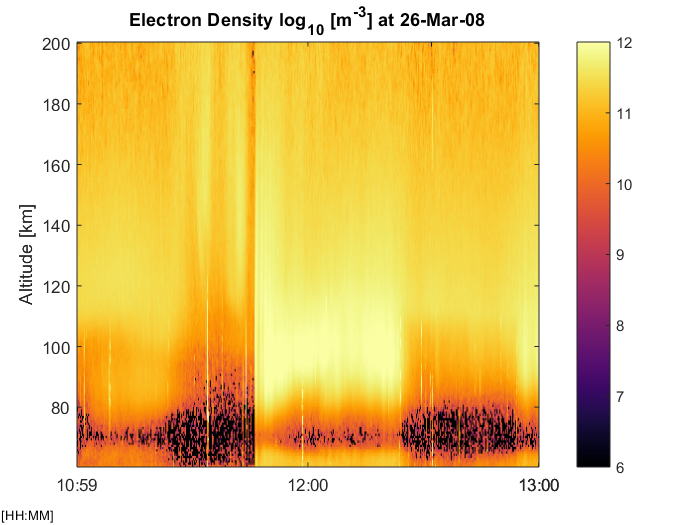

figure;
z = squeeze(mean(data.electronDensity,2));
z(z<=0)=10^3;
plot_2D_time_series(data.time',data.alt',log10(z)',1,1,timeMinStr,timeMaxStr);
colormap('inferno');
caxis([6 12]);
colorbar;

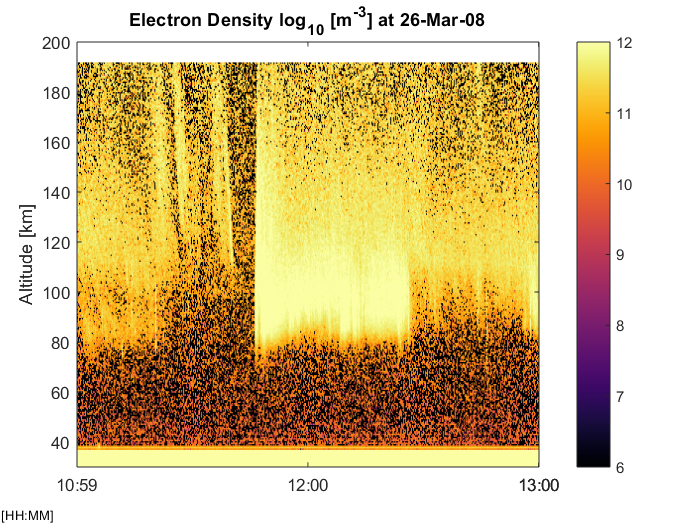

figure;
iBeam = 4;
z = squeeze((permute(amisr.electronDensity(:,iBeam,:),[3 2 1])));
z(z<=0)=10^3;
plot_2D_time_series(amisr.time(1,:)',amisr.altitude(:,iBeam)',log10(z)',1,1,timeMinStr,timeMaxStr);
colormap('inferno');
ylim([30 200]);
caxis([6 12]);
colorbar;


figure;
iBeam = 4;
% z = squeeze(mean(permute(amisrData.magElectronDensity,[3 2 1]),2));
z = squeeze((permute(amisrData.magElectronDensity(:,iBeam,2555:end),[3 2 1])));
z(z<=0)=10^3;
time = crop_time(amisrData.time(1,:),amisrData.time(1,:),timeMinStr,timeMaxStr);
plot_2D_time_series(time,amisrData.magCartCoords.zUp(:,iBeam)',log10(z)',1,1);

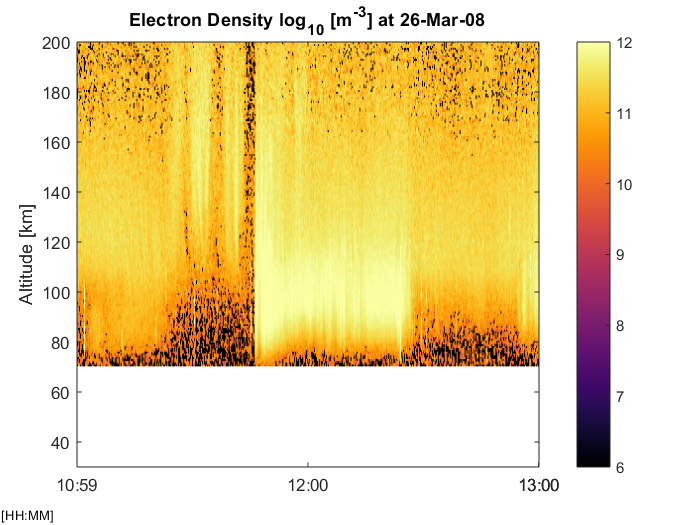

colormap('inferno');
ylim([30 200]);
caxis([6 12]);
colorbar;

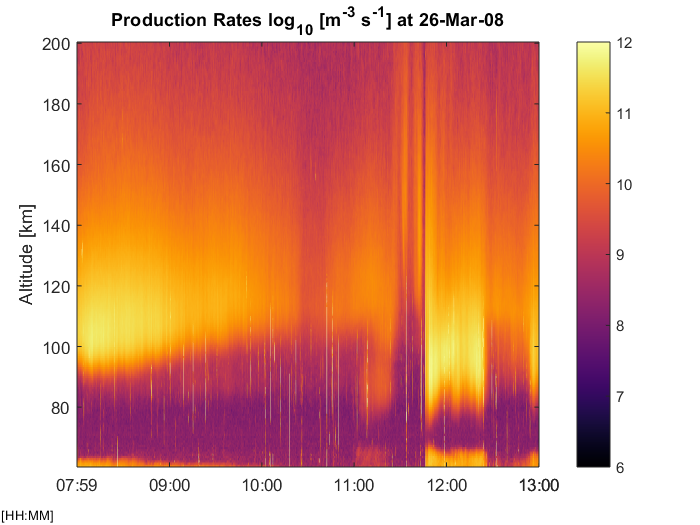


figure;
z = squeeze(mean(data.qInput,2));
z(z<=0)=10^3;
plot_2D_time_series(data.time',data.alt',log10(z)',1,2,timeMinStr,timeMaxStr);
colormap('inferno');
caxis([6 12]);
colorbar;

## Investigating the neflection

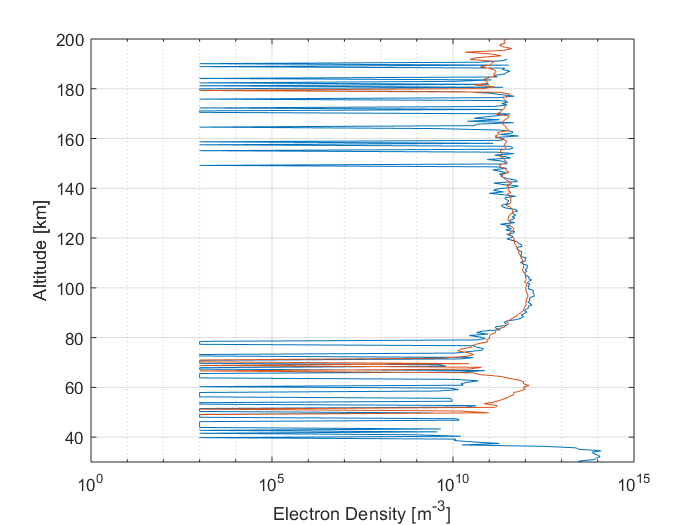


figure; 
iBeam = 4;
z = squeeze((permute(amisr.electronDensity(:,iBeam,:),[3 2 1])));
z(z<=0)=10^3;
plot_1D_time_slice(amisr.time(1,:)',amisr.altitude(:,iBeam)',z','26 Mar 2008 12:00',1);
ylim([60 200]);
hold on;
z1 = squeeze((permute(amisrData.magElectronDensity(:,iBeam,:),[3 2 1])));
z1(z1<=0)=10^3;
plot_1D_time_slice(amisrData.time(1,:)',amisrData.magCartCoords.zUp(:,iBeam)',z1','26 Mar 2008 12:00',1);
ylim([30 200]);